# HDC - Deconvolution

This script is used for the publication titled "**Negotiating System’s Band Broadening in Hydrodynamic Chromatography for the Determination of Particle-Size Distributions of Polymeric Nanoparticles**", authored by J. Verduin, J.D. Kruijswijk et al.

Please first import the matlab dat file titled "HDC_deconvolution.mat" in order to run this script.

This script is used for: 

- Visualization of the recorded HDC-UV chromatograms of PS blends and PLGA NPs;

- Deconvolution of NP samples using the function "gauss4.m"; 

- For symmterical distributions, "gausseqv" is used in the function gauss4.m

- For asymmetrical distributions, "gauss" is used with weights = true in de function gauss4.m;

- Application of the UV response curve if needed.

Note: This script is hard-coded for the few samples studied. Automation is possible but requires adjustments of this original script.

# Preparing the data

## Importing the data

% Run this per data set
%%% HDC_PSmix.AIA and HDC_PSmix_II.AIA
Data = dir('*.cdf');                                    % Make sure to be in correct directory
file_paths = fullfile({Data.folder}, {Data.name});
[Data.path] = file_paths{:};
DataCell = [];
for i=1:length(Data)
    NameCDF= Data(i).name;
     Actual_Name = char(file_paths(i));
     ncid= netcdf.open(Actual_Name, 'NC_NOWRITE');
     Name_Signal= ncreadatt(Actual_Name,'/','detector_name');
     Sample_name = ncreadatt(Actual_Name,'/','sample_name');
     Method_name = ncreadatt(Actual_Name,'/','detection_method_name');
     Signal = ncread(Actual_Name, 'ordinate_values');
     Run_time_length = ncread(Actual_Name, 'actual_run_time_length');
     Time = (0:Run_time_length/60/(length(Signal)-1):Run_time_length/60)';
     Sampling_rate= ncread(Actual_Name,'actual_sampling_interval');
     netcdf.close(ncid);
     DataCell= [DataCell {Name_Signal;Sample_name;Method_name;Signal;Time;Run_time_length;Sampling_rate}];
end
[Data.Signal_type] = DataCell{1,:};

Brace indexing is not supported for variables of this type.

[Data.Sample_name] = DataCell{2,:};
[Data.Method] = DataCell{3,:};
[Data.Signal] = DataCell{4,:};
[Data.Time] = DataCell{5,:};
[Data.Run_Time] = DataCell{6,:};
[Data.Sampling_rate] = DataCell{7,:};

## Sorting the data

% PSmix indices

% Run this part for HDC_PSmix.AIA 
%%% 7201 = 12 min
mix1_ind = [6 2 10 14 17 19 23 27 31 35 39 43];
time = Data(2).Time(7201:9000);
mix1_data = zeros(length(time),length(mix1_ind));
for i = 1:length(mix1_ind)
    for j = mix1_ind(i)
        mix1_data(:,i) = Data(j).Signal(7201:9000);
    end
end

% Run this part for HDC_PSmix_II.AIA
mix2_ind = [2 22 6 10 14 18 26];
time = Data(2).Time(7201:9000);
mix2_data = zeros(length(time),length(mix2_ind));
for i = 1:length(mix2_ind)
    for j = mix2_ind(i)
        mix2_data(:,i) = Data(j).Signal(7201:9000);
    end
end

% Combine data sets
mix1_ind = [2 8 9 10 11 12]; % 30-50-70, 50-100-200, 50-200-500, 500-700-900, 20-30, 100-200-350
mix2_ind = [2 3 4 5 6 7];  % 30-50-70, 50-100-200, 50-200-500, 500-700-900, 20-30, 100-200-350
singles_ind = [1 3 4 5 6 7];  % t0 + extra mix (singles): 20-900, 30-900, 50-500, 100-200, 30-50-100

rep_1 = zeros(length(mix1_data), length(mix1_ind)); % part 1/2 of mix duplo's
rep_2 = zeros(length(mix2_data), length(mix2_ind)); % part 2/2 of mix duplo's
singles = zeros(length(mix1_data), length(singles_ind)); % single measurements, t0 + remaining mixtures
for i = 1:length(mix1_ind)
    for j = mix1_ind(i)
        for k = mix2_ind(i)
            rep_1(:,i) = mix1_data(:,j);
            rep_2(:,i) = mix2_data(:,k);
        end
    end
    for l = 1:length(singles_ind)
        for m = singles_ind(l)
            singles(:,l) = mix1_data(:,m);
        end
    end
end
reps = [rep_1 rep_2];

% Plotting the repeats
colors_list = {'#0D2747','#D06D91','#567964','#CC9900','#59595F','#833DAB','#2A60A5','#EFBED0','#7BAD8F','#F9D14A','#A7A7A7','#9877AB'};
figure
for i = 1:12
    hold on
    plot(time,reps(:,i), 'LineWidth', 2, 'color', colors_list{(i)})
    hold off
    set(gca, 'FontSize', 14); 
    ax = gca; 
    xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
    xlim([12.6 14.2]);
    ylim([0 500]);
end

figure
for i = 1:12
    hold on
    reps_norm(:,i) = reps(:,i)./max(reps(:,i));
    plot(time,reps_norm(:,i), 'LineWidth', 2, 'color', colors_list{(i)})
    hold off
    set(gca, 'FontSize', 14); 
    ax = gca; 
    xlabel('Time (min)'); ylabel('Normalized intensity'); 
    xlim([12.6 14.2]);
    ylim([0 1.05]);
end

% Plotting the singles
colors_list = {'#0D2747','#D06D91','#567964','#CC9900','#59595F','#833DAB','#2A60A5','#EFBED0','#7BAD8F','#F9D14A','#A7A7A7','#9877AB'};
figure
for i = 1:length(singles_ind)
    hold on
    plot(time,singles(:,i), 'LineWidth', 2, 'color', colors_list{(i)})
    hold off
    set(gca, 'FontSize', 14); 
    ax = gca; 
    xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
    xlim([12.8 14.2]);
    ylim([0 500]);
end

figure
for i = 1:length(singles_ind)
    hold on
    singles_norm(:,i) = singles(:,i)./(max(singles(:,i)));
    plot(time,singles_norm(:,i), 'LineWidth', 2, 'color', colors_list{(i)})
    hold off
    set(gca, 'FontSize', 14); 
    ax = gca; 
    xlabel('Time (min)'); ylabel('Normalized intensity'); 
    xlim([12.8 14.2]);
    ylim([0 1.05]);
end


% Use this figure to visualize the mixtures
figure
hold on
plot(time, reps(:,2), 'LineWidth', 2,'color','#0D2747');
plot(time, reps(:,8), 'LineWidth', 2,'color','#2A60A5');
%plot(time, singles(:,6), 'LineWidth', 2,'color','#0D2747');
hold off
xlabel('Time (min)'); ylabel('Intensity'); 
ax = gca; 
set(gca, 'FontSize', 14);
xlim([12.5,14.2]);
%ylim([0, end]);
legend('Repeat 1','Repeat 2');
legend ('boxoff');
legend ('location','northwest');


% Data used
rep_idx = [1 2 8 3 9 4 10 6 12];
singles_idx = [2 3 4 5 6];
m1 = zeros(length(reps),length(rep_idx));
m2 = zeros(length(reps),length(singles_idx));

for i = 1:length(rep_idx)
    for j = rep_idx(i)
        m1(:,i) = reps(:,j);
    end
end
for k = 1:length(singles_idx)
    for l = singles_idx(k)
        m2(:,k) = singles(:,l);
    end
end
mtot = [m1 m2];
mix = mtot./max(mtot);

# Construction deconvoluted, corrected chromatograms

## Obtain parameters from Simulated_HDC_chromatograms.mlx

max_STD_var = 0.0001042; % from Excel (minimum observable PSD)
x_size = polyval(p_size,time);

## Obtain fitted parameters from SLN results

% [height, position, sigma, variance (var_tot)];
%%% Gaussian samples
A = [202.82 13.91 0.10 0.01001968];
E = [113.57	13.20 0.08 0.00567782; 
    418.16 13.54 0.09 0.00745650;
    74.50 13.94 0.09 0.00781647];
F = [20.22 12.92 0.06 0.00411065];
G = [24.16 12.91 0.07 0.00478605;
    23.83 14.05 0.10 0.00920915];
H = [111.45 13.20 0.07 0.00557435;
    77.53 13.94 0.09 0.00793061];
J = [230.45 13.80 0.12 0.01518483];

%%% Gaussian/non-Gaussian samples
B = [401.84 13.55 0.10 0.01063186;
    147.38 13.77 0.05 0.00208474];
C = [132.40 13.19  0.09 0.00783568;
    56.41 13.44 0.002 0.00000289];
D = [101.08 13.39 0.02 0.00025056
    438.43 13.52 0.16 0.02563802;
    121.54 13.76 0.03 0.00094409];
I = [388.76 13.55 0.11 0.01274475;
    133.85 13.76 0.03 0.00121159];

mix_par = [A;E;F;G;H;J;B;C;D;I];

% Determine var_res (corrected variance)
var_sys = polyval(p_var_2,mix_par(:,2));        % system variance based on PS NP calibration
var_tot = mix_par(:,4);                         % variance of deconvoluted signal
var_res_temp = var_tot - var_sys;               % residual variance (without LOD correction)
low_var_res = var_res_temp < max_STD_var;       % LOD correction: var_res_temp = max_STD_var if var_res_temp < max_STD_var
var_res = zeros(length(var_res_temp),1);
for i = 1:length(var_res_temp)
    if low_var_res(i,:) == 1
        var_res(i,:) = max_STD_var;             % LOD of observable variance
    else
        var_res(i,:) = var_res_temp(i,:);       % above LOD of observable variance
    end
end
sig_res = sqrt(var_res);

% General notes: This part is quite hard-coded, so pay attention to the instructions below

%%% gauss4(time, signal, n, weights, pop1, pop2, pop3, deconmode (= "gauss" for asymmetrical or "gausseqv" for symmetrical))
%%% Always first perform the deconvolution on the recorded HDC-UV chromatogram
%%% Manually insert the peak parameters to construct the var_sys-corrected chromatograms, annotated as 'cor_t1', 'cort_2', and 'cor_t3'
%%% Re-run the gauss4 if you want to visualize the deconvoluted plots with these corrected chromatograms 
%%% (just use dummy chromatograms if you do this for the first time)
%%% Make sure to update the corrected chromatograms if you start working on a new recorded chromatogram

## Straightforward symmetrical fitting and correction ("gausseqv")

colors_list = { '#0D2747' '#D06D91' '#567964' '#CC9900' '#59595F' '#833DAB' '#2A60A5' '#EFBED0' '#7BAD8F' '#F9D14A' '#A7A7A7' '#9877AB'};

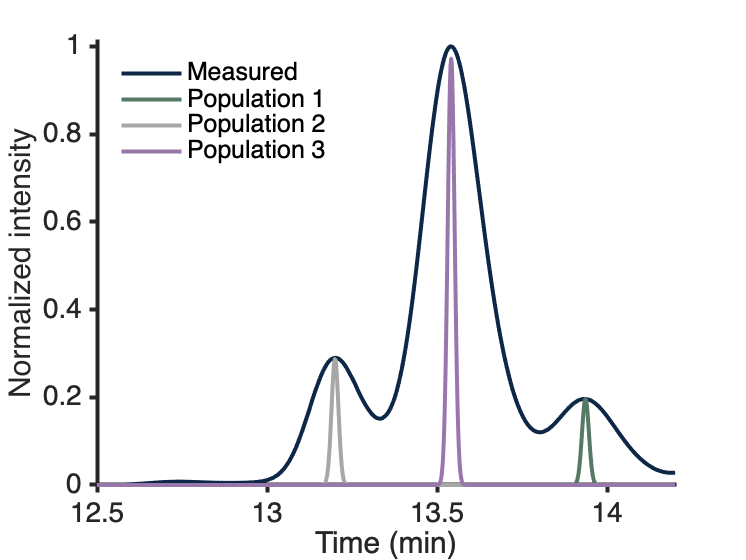

% Sample B 50+200+500
i = 2; j = 3; k = 4; % peak parameter indices
l = 4; % measured chromatogram index

%%% Time chromatogram
%%% Note that for all corrected chromatograms, the signals are normalized based on the deconvoluted peak heights
cor_t1 = gauss(time,0.1961,13.9367,0.010209034); cor_t1_n = (cor_t1./max(cor_t1))*0.196057;
cor_t2 = gauss(time,0.2873,13.2,0.010209034); cor_t2_n = (cor_t2./max(cor_t2))*0.287567;
cor_t3 = gauss(time,0.9734,13.5417,0.010209034); cor_t3_n = (cor_t3./max(cor_t3))*0.972627;

figure
hold on
plot(time,mix(:,l),'LineWidth',2,'color', colors_list{1})
plot(time,cor_t1_n,'LineWidth',2,'color', colors_list{3})
plot(time,cor_t2_n,'LineWidth',2,'color', colors_list{11})
plot(time,cor_t3_n,'LineWidth',2,'color', colors_list{12})
hold off
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.5 14.2]);
ylim([0 1.01]);
legend('Measured','Population 1','Population 2','Population 3');
legend('boxoff')
legend('location','northwest')

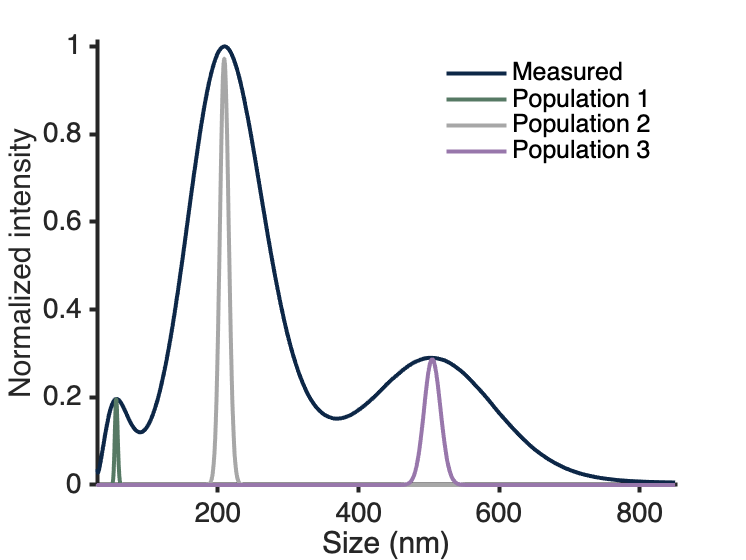


% Size chromatogram
figure
hold on
plot(x_size(1:1349),(mix(1:1349,l)),'LineWidth',2,'color', colors_list{1}) % measured chrom
plot(x_size(1:1349),cor_t1_n(1:1349),'LineWidth',2,'color', '#567964') % 50
plot(x_size(1:1349),cor_t3_n(1:1349),'LineWidth',2,'color', '#A7A7A7') % 200
plot(x_size(1:1349),cor_t2_n(1:1349),'LineWidth',2,'color', '#9877AB') % 500
hold off
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([28 850]);
ylim([0 1.01]);
legend('Measured','Population 1','Population 2','Population 3');
legend('boxoff')
legend('location','northeast')


% Calculate size peak parameters
[x_unique, idx_unique, uniques] = unique(x_size(1:1349),'rows');    % determine unique size values, without duplicates

for i = 1:length(idx_unique)
    for j = idx_unique(i)
        x_unique(i) = x_size(j);        % size values without duplicates, needed for findpeaks
        p1_525(i) = cor_t1_n(j,:);      % population 1
        p2_525(i) = cor_t2_n(j,:);      % population 2
        p3_525(i) = cor_t3_n(j,:);      % population 3
    end
end

populations = [p1_525; p2_525; p3_525]';
for k = 1:size(populations,2)
    [hgts(k) locs(k) wds(k)] = findpeaks(populations(:,k), x_unique(:,1),'MinPeakHeight',0.15);
end

sigma = [wds./2.35];
var = sigma.^2;
p_525 = [locs; sigma; var]';

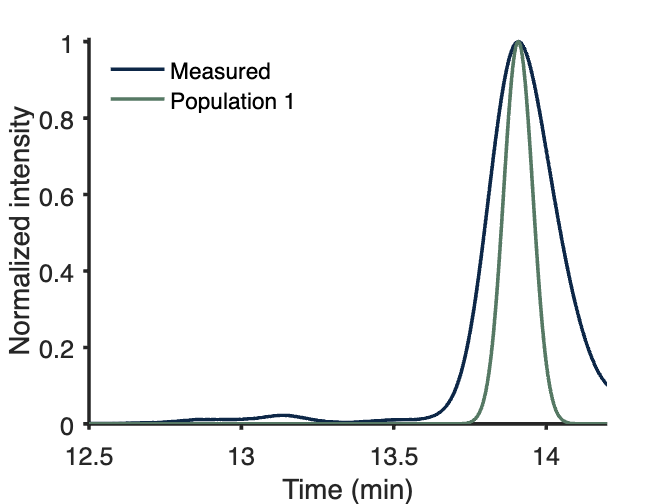

% Sample A 30+50+70
i = 1; % peak parameter indices
l = 1; % measured chromatogram index

%%% Time chromatogram
%cor_t1 = gauss(time,mix_par(i,1),mix_par(i,2),sig_res(i,1)); cor_t1_n = cor_t1./max(cor_t1);
cor_t1 = gauss(time,1,13.9083,0.047960922); cor_t1_n = (cor_t1./max(cor_t1))*0.999994;
figure
hold on
plot(time,mix(:,l),'LineWidth',2,'color', colors_list{1})
plot(time,cor_t1_n,'LineWidth',2,'color', colors_list{3})
hold off 
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.5 14.2]);
ylim([0 1.01]);
legend('Measured','Population 1');
legend('boxoff')
legend('location','northwest')

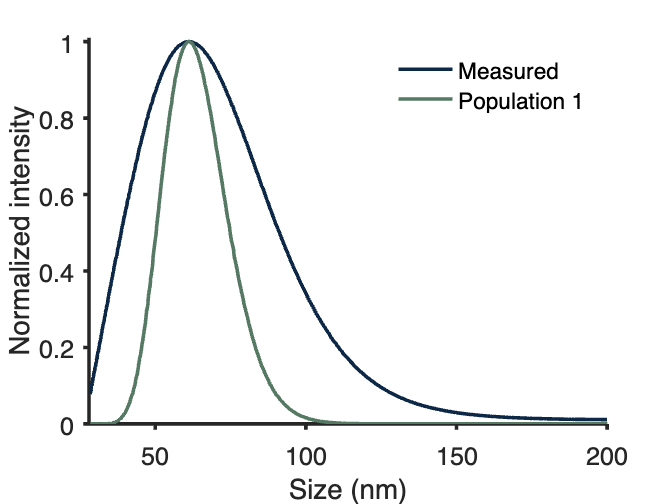


% Size chromatogram
figure
hold on
plot(x_size(1:1349),(mix(1:1349,l)),'LineWidth',2,'color', colors_list{1}) % measured chrom
plot(x_size(1:1349),cor_t1_n(1:1349),'LineWidth',2,'color', colors_list{3})
hold off
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([28 200]);
ylim([0 1.01]);
legend('Measured','Population 1');
legend('boxoff')
legend('location','northeast')


% Calculate size peak parameters
for i = 1:length(idx_unique)
    for j = idx_unique(i)
        x_unique(i) = x_size(j);        % size values without duplicates, needed for findpeaks
        p1_357(i) = cor_t1_n(j,:);      % population 1
    end
end

[hgts, locs, wds] = findpeaks(p1_357, x_unique(:,1), 'MinPeakHeight',0.9);
sigma = [wds/2.35];
var = sigma.^2;
p_357 = [locs; sigma; var]';

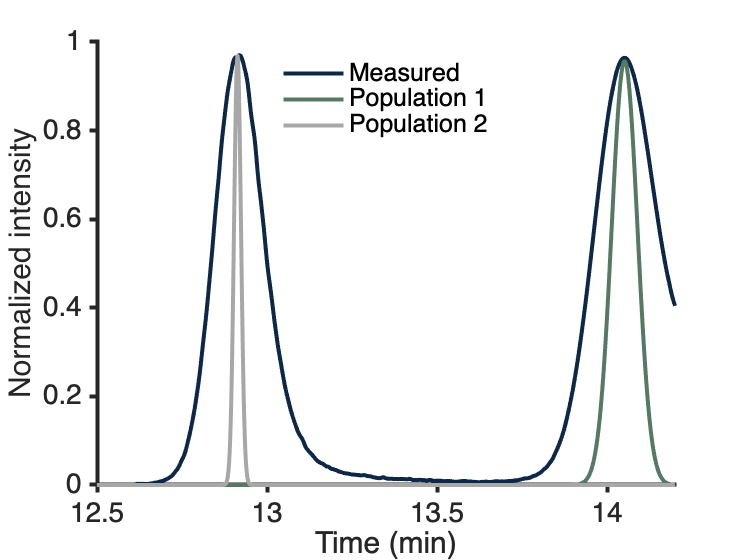

% Sample C 30+900
i = 6; j = 7; % peak parameter indices
l = 11; % measured chromatogram index

%%% Time chromatogram
cor_t1 = gauss(time,0.9869,14.0517,0.038000132); cor_t1_n = (cor_t1./max(cor_t1))*0.9569;
cor_t2 = gauss(time,0.9999,12.9133,0.010209034); cor_t2_n = (cor_t2./max(cor_t2))*0.9699;
figure
hold on
plot(time,(mix(:,l)-0.03),'LineWidth',2,'color', colors_list{1})
plot(time,cor_t1_n,'LineWidth',2,'color', colors_list{3})
plot(time,cor_t2_n,'LineWidth',2,'color', colors_list{11})
hold off
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.5 14.2]);
ylim([0 1]);
legend('Measured','Population 1','Population 2');
legend('boxoff')
legend('location','north')

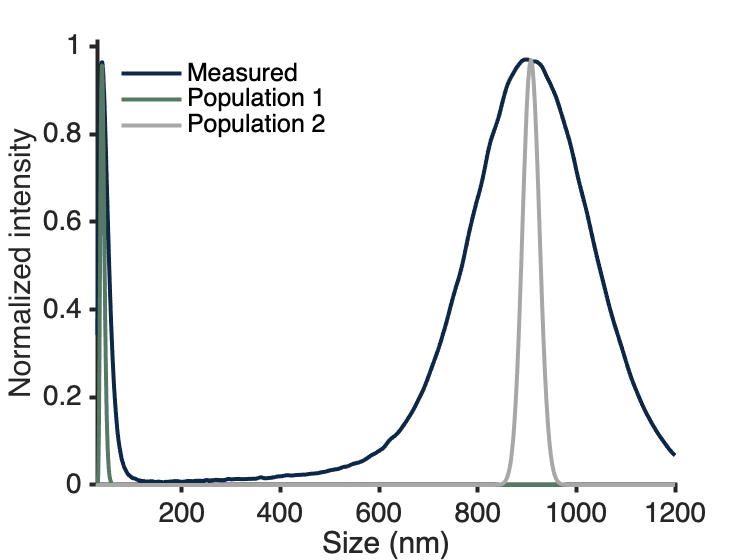


% Size chromatogram
figure
hold on
plot(x_size(1:1349),(mix(1:1349,l)-0.03),'LineWidth',2,'color', colors_list{1}) % measured chrom
plot(x_size(1:1349),cor_t1_n(1:1349),'LineWidth',2,'color', colors_list{3})
plot(x_size(1:1349),cor_t2_n(1:1349),'LineWidth',2,'color', colors_list{11})
hold off
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([28 1200]);
ylim([0 1.01]);
legend('Measured','Population 1','Population 2');
legend('boxoff')
legend('location','northwest')


% Calculate size peak parameters
for i = 1:length(idx_unique)
    for j = idx_unique(i)
        p1_39(i) = cor_t1_n(j,:);      % population 1
        p2_39(i) = cor_t2_n(j,:);      % population 2
    end
end

populations = [p1_39; p2_39]';
for k = 1:size(populations,2)
    [hgts(k), locs(k), wds(k)] = findpeaks(populations(:,k), x_unique(:,1),'MinPeakHeight',0.9);
end
sigma = [wds./2.35];
var = sigma.^2;
p_39 = [locs; sigma; var]';

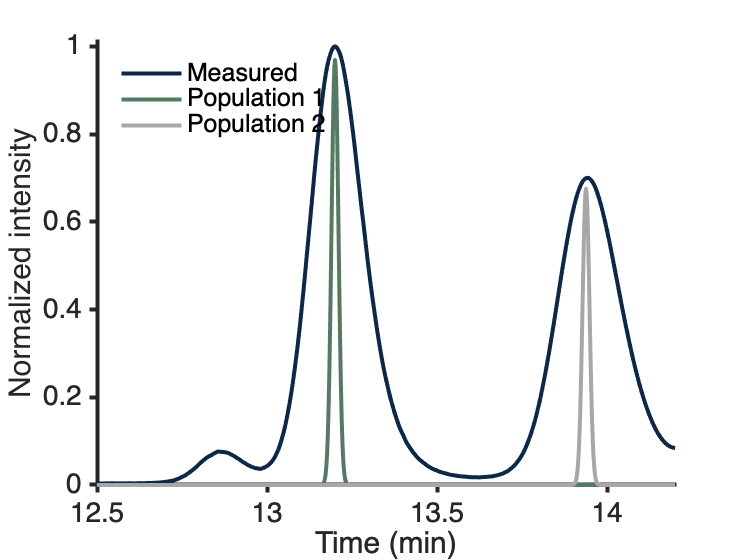

% Sample D 50+500
i = 8; j = 9; % peak parameter indices
l = 12; % measured chromatogram index

%%% Time chromatogram
cor_t1 = gauss(time,0.97,13.2,0.010209034); cor_t1_n = (cor_t1./max(cor_t1))*0.97;
cor_t2 = gauss(time,0.676377,13.9383,0.010209034); cor_t2_n = (cor_t2./max(cor_t2))*0.676377;
figure
hold on
plot(time,mix(:,l),'LineWidth',2,'color', colors_list{1})
plot(time,cor_t1_n,'LineWidth',2,'color', colors_list{3})
plot(time,cor_t2_n,'LineWidth',2,'color', colors_list{11})
hold off
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.5 14.2]);
ylim([0 1.01]);
legend('Measured','Population 1','Population 2');
legend('boxoff')
legend('location','northwest')

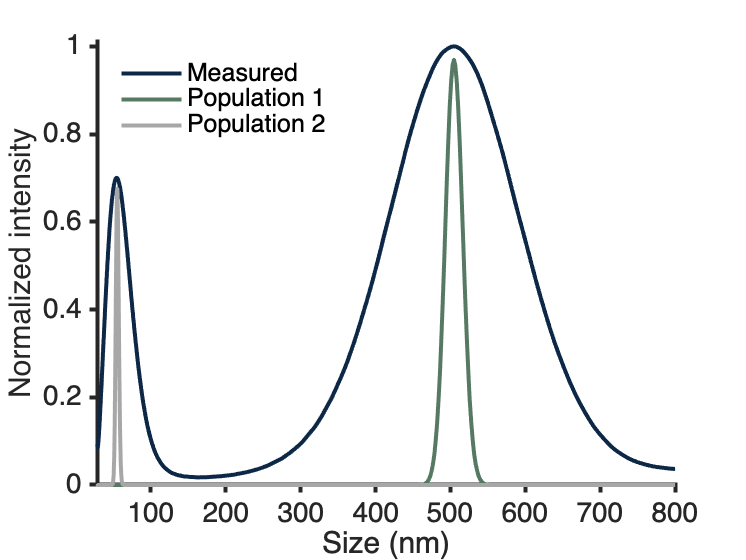


% Size chromatogram
figure
hold on
plot(x_size(1:1349),(mix(1:1349,l)),'LineWidth',2,'color', colors_list{1}) % measured chrom
plot(x_size(1:1349),cor_t1_n(1:1349),'LineWidth',2,'color', colors_list{3})
plot(x_size(1:1349),cor_t2_n(1:1349),'LineWidth',2,'color', colors_list{11})
hold off
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([28 800]);
ylim([0 1.01]);
legend('Measured','Population 1','Population 2');
legend('boxoff')
legend('location','northwest')


% Calculate size peak parameters
for i = 1:length(idx_unique)
    for j = idx_unique(i)
        p1_55(i) = cor_t1_n(j,:);      % population 1
        p2_55(i) = cor_t2_n(j,:);      % population 2
    end
end

populations = [p1_55; p2_55]';
for k = 1:size(populations,2)
    [hgts(k), locs(k), wds(k)] = findpeaks(populations(:,k), x_unique(:,1),'MinPeakHeight',0.9);
end

Unable to perform assignment because the left and right sides have a different number of elements.

sigma = [wds./2.35];
var = sigma.^2;
p_55 = [locs; sigma; var]';

## Overview populations

gauss_pops = [p_357; p_525; p_39; p_55; p_351]; % size, sigma, variance, each row is size population

## Asymmetrical fitting and correction (gauss4 "gauss", weights = true)-> extra manual assessment

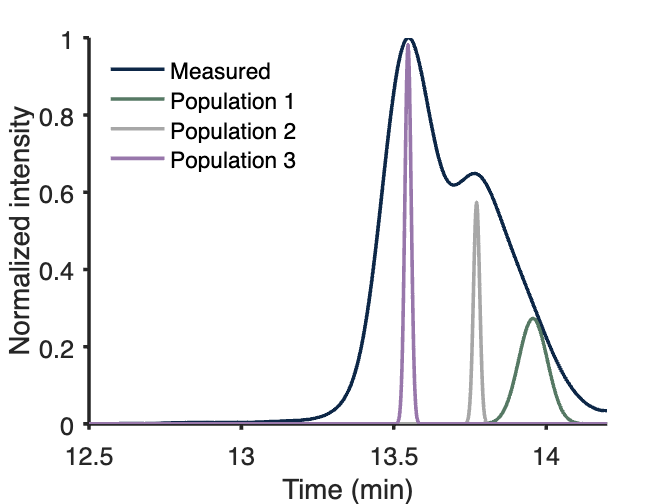

% Sample E (50+100+200)
% 3 populations
%%% Time chromatogram
n3_p1 = gauss(time,0.273,13.9567,0.047116982); n3_p1_n = (n3_p1./max(n3_p1))*0.27284;
n3_p2 = gauss(time,0.5733,13.7717,0.010209034); n3_p2_n = (n3_p2./max(n3_p2))*0.572676;
n3_p3 = gauss(time,0.982,13.5467,0.010209034); n3_p3_n = (n3_p3./max(n3_p3))*0.981326;

figure
hold on
plot(time,mix(:,2), 'LineWidth', 2,'color','#0D2747');
plot(time,n3_p1_n, 'LineWidth', 2,'color','#567964');
plot(time,n3_p2_n, 'LineWidth', 2,'color','#A7A7A7');
plot(time,n3_p3_n, 'LineWidth', 2,'color','#9877AB');
hold off
xlabel('Time (min)'); ylabel('Normalized intensity'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca; 
xlim([12.5,14.2]);
legend('Measured','Population 1','Population 2','Population 3');
legend ('boxoff');
legend ('location','northwest');

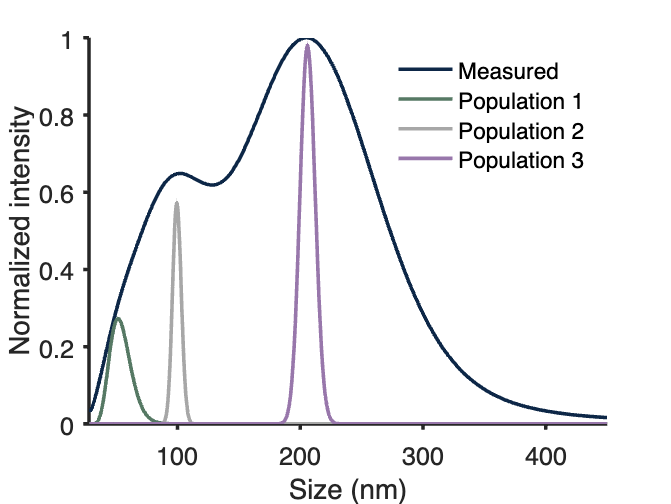


%%% Size chromatogram
figure
hold on
plot(x_size(1:1349),mix(1:1349,2), 'LineWidth', 2,'color','#0D2747');
plot(x_size(1:1349), n3_p1_n(1:1349), 'LineWidth', 2,'color','#567964');
plot(x_size(1:1349),n3_p2_n(1:1349), 'LineWidth', 2,'color','#A7A7A7');
plot(x_size(1:1349),n3_p3_n(1:1349), 'LineWidth', 2,'color','#9877AB');
hold off
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca; 
xlim([28,450]);
legend('Measured','Population 1','Population 2','Population 3');
legend ('boxoff');
legend ('location','northeast');


% Calculate size peak parameters
for i = 1:length(idx_unique)
    for j = idx_unique(i)
        p1_512(i) = n3_p1_n(j,:);      % population 1
        p2_512(i) = n3_p2_n(j,:);      % population 2
        p3_512(i) = n3_p3_n(j,:);      % population 3
    end
end

populations = [p1_512; p2_512; p3_512]';
for k = 1:size(populations,2)
    [hgts(k), locs(k), wds(k)] = findpeaks(populations(:,k), x_unique(:,1),'MinPeakHeight',0.9);
end

Unable to perform assignment because the left and right sides have a different number of elements.

sigma = [wds./2.35];
var = sigma.^2;
p_512 = [locs; sigma; var]';

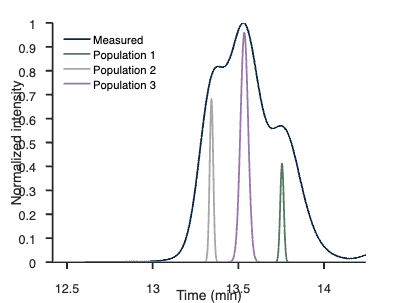

% Sample F (100+200+350)
%%% Fitted with 4 distributions, but 1 distribution under LOD, so 3 distributions in total

% 3 populations
%%% Time chromatogram
n3_p1 = gauss(time,0.413,13.755,0.010209034); n3_p1_n = (n3_p1./max(n3_p1))*0.41294;
n3_p2 = gauss(time,0.686,13.3433,0.010209034); n3_p2_n = (n3_p2./max(n3_p2))*0.681627;
n3_p3 = gauss(time,0.9623,13.535,0.022432343); n3_p3_n = (n3_p3./max(n3_p3))*0.959884;

figure
hold on
plot(time,mix(:,8), 'LineWidth', 2,'color','#0D2747');
plot(time,n3_p1_n, 'LineWidth', 2,'color','#567964');
plot(time,n3_p2_n, 'LineWidth', 2,'color','#A7A7A7');
plot(time,n3_p3_n, 'LineWidth', 2,'color','#9877AB');
hold off
xlabel('Time (min)'); ylabel('Normalized intensity'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca; 
xlim([12.5,14.2]);
legend('Measured','Population 1','Population 2','Population 3');
legend ('boxoff');
legend ('location','northwest');

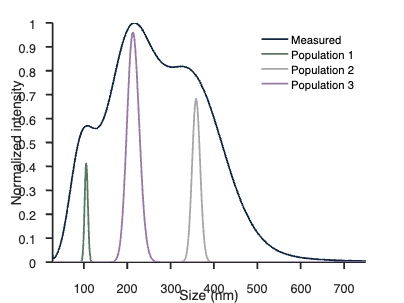


%%% Size chromatogram
figure
hold on
plot(x_size(1:1349),mix(1:1349,8), 'LineWidth', 2,'color','#0D2747');
plot(x_size(1:1349), n3_p1_n(1:1349), 'LineWidth', 2,'color','#567964');
plot(x_size(1:1349),n3_p2_n(1:1349), 'LineWidth', 2,'color','#A7A7A7');
plot(x_size(1:1349),n3_p3_n(1:1349), 'LineWidth', 2,'color','#9877AB');
hold off
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca; 
xlim([28,750]);
legend('Measured','Population 1','Population 2','Population 3');
legend ('boxoff');
legend ('location','northeast');


% Calculate size peak parameters
for i = 1:length(idx_unique)
    for j = idx_unique(i)
        p1_123(i) = n3_p1_n(j,:);      % population 1
        p2_123(i) = n3_p2_n(j,:);      % population 2
        p3_123(i) = n3_p3_n(j,:);      % population 3
    end
end

populations = [p1_123; p2_123; p3_123]';
for k = 1:size(populations,2)
    [hgts(k), locs(k), wds(k)] = findpeaks(populations(:,k), x_unique(:,1),'MinPeakHeight',0.4);
end
sigma = [wds./2.35];
var = sigma.^2;
p_123 = [locs; sigma; var]';

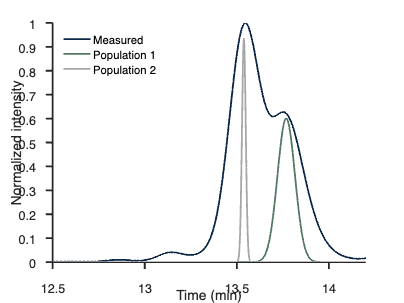

% Sample G (100+200)
n2_p1 = gauss(time,0.6016,13.7683,0.047329061); n2_p1_n = (n2_p1./max(n2_p1))*0.600923;
n2_p2 = gauss(time,0.9526,13.5383,0.010209034); n2_p2_n = (n2_p2./max(n2_p2))*0.932617;

%%% Time chromatogram
figure
hold on
plot(time,mix(:,13), 'LineWidth', 2,'color','#0D2747');
plot(time,n2_p1_n, 'LineWidth', 2,'color','#567964');
plot(time,n2_p2_n, 'LineWidth', 2,'color','#A7A7A7');
hold off
xlabel('Time (min)'); ylabel('Normalized intensity'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca; 
xlim([12.5,14.2]);
legend('Measured','Population 1','Population 2');
legend ('boxoff');
legend ('location','northwest');

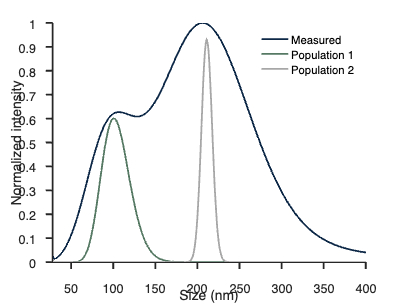


%%% Size chromatogram
figure
hold on
plot(x_size(1:1349),mix(1:1349,13), 'LineWidth', 2,'color','#0D2747');
plot(x_size(1:1349), n2_p1_n(1:1349), 'LineWidth', 2,'color','#567964');
plot(x_size(1:1349),n2_p2_n(1:1349), 'LineWidth', 2,'color','#A7A7A7');
hold off
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca; 
xlim([28,400]);
legend('Measured','Population 1','Population 2');
legend ('boxoff');
legend ('location','northeast');


% Calculate size peak parameters
for i = 1:length(idx_unique)
    for j = idx_unique(i)
        p1_12(i) = n2_p1_n(j,:);      % population 1
        p2_12(i) = n2_p2_n(j,:);      % population 2
    end
end

populations = [p1_12; p2_12]';
for k = 1:size(populations,2)
    [hgts(k), locs(k), wds(k)] = findpeaks(populations(:,k), x_unique(:,1),'MinPeakHeight',0.5);
end
sigma = [wds./2.35];
var = sigma.^2;
p_12 = [locs(1:2); sigma(1:2); var(1:2)]';

# PLGA UV correction + PSD extraction

## Measurement overview and UV response

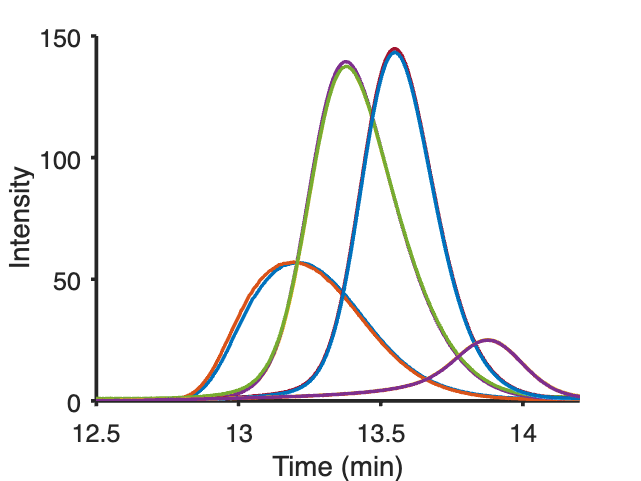

% Overview PLGA chromatograms
PLGA = PLGAa(7201:9000,:);

figure 
hold on
for i = 2:12
    plot(time,PLGA(:,i), 'LineWidth', 2)
end
xlabel('Time (min)'); ylabel('Intensity'); 
ax = gca; 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlim([12.5,14.2]);
ylim([0, 150]);
hold off

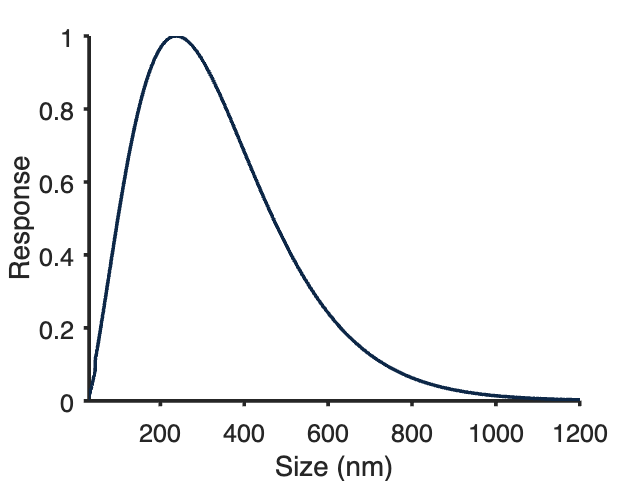

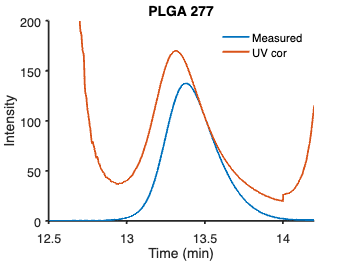

% UV response curve
%%% UV_trend from Excel fitted UV trend based on PS peak tops
%%% [time, raw fit, normalized fit]
figure
hold on
plot(x_size(1:1349),UV_trend(1:1349,2)./max(UV_trend(1:1349,2)), 'LineWidth', 2,'color','#0D2747')
xlabel('Size (nm)'); ylabel('Response'); 
ax = gca; 
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlim([30,1200]);
ylim([0,1]);
hold off

## Symmetrical distributions (277 and 229 nm) ("gausseqv")

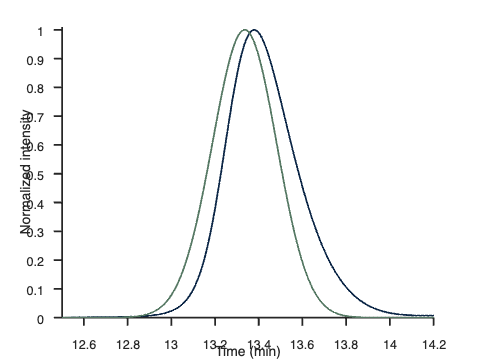

% PLGA 277
PLGA_277_n = PLGA(:,4)./max(PLGA(:,4));
PLGA_277_p1 = gauss(time,0.9959,13.3833,0.122324323); p1_277_n = (PLGA_277_p1./max(PLGA_277_p1))*0.997221;
PLGA_277_UV = p1_277_n.*(1./UV_trend(:,2)); UV_PLGA_277 = PLGA_277_UV./max(PLGA_277_UV);

figure
hold on
plot(time,PLGA_277_n,'LineWidth',2,'color', '#0D2747'); % measured chrom
%plot(time,cor_277_n,'LineWidth',2,'color', '#CC9900'); % corrected chrom before UV cor
plot(time,UV_PLGA_277,'LineWidth',2,'color', '#567964'); % corrected chrom after UV cor
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.5 14.2]);
ylim([0 1.01]);
hold off
%legend('Measured','Corrected','UV corrected');
%legend('boxoff')
%legend('location','northeast')

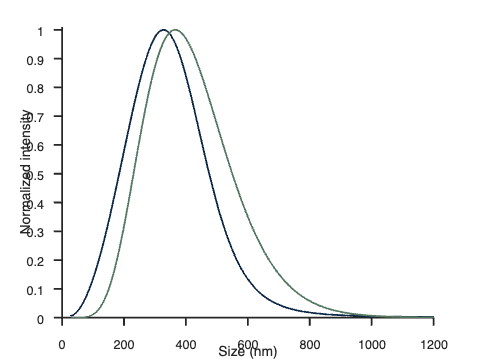


figure
hold on
plot(x_size(1:1349),PLGA_277_n(1:1349),'LineWidth',2,'color', '#0D2747'); % measured chrom
%plot(x_size(1:1349),cor_277_n(1:1349),'LineWidth',2,'color', '#CC9900'); % corrected chrom before UV cor
plot(x_size(1:1349),UV_PLGA_277(1:1349),'LineWidth',2,'color', '#567964'); % corrected chrom after UV cor
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([0 1200]);
ylim([0 1.01]);
hold off

for i = 1:length(idx_unique)
    for j = idx_unique(i)

        p_277_n(i) = p1_277_n(j,:);      % population 1
    end
end

[hgts_UV, locs_UV, wds_UV] = findpeaks(p_277_n, x_unique(:,1), 'MinPeakHeight',0.9);
sigma_UV = [wds_UV/2.35];
var_UV = sigma_UV.^2;
p_277_UV = [locs_UV; sigma_UV; var_UV]';

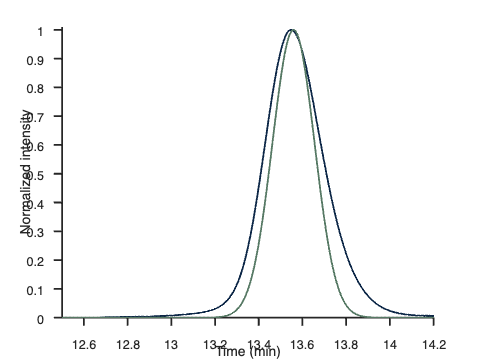

% PLGA 229
PLGA_229_n = PLGA(:,7)./max(PLGA(:,7));
PLGA_229_p1 = gauss(time,1,13.55,0.08916552); p1_229_n = (PLGA_229_p1./max(PLGA_229_p1))*1;
PLGA_229_UV = p1_229_n.*(1./UV_trend(:,2)); UV_PLGA_229 = PLGA_229_UV./max(PLGA_229_UV);

figure
hold on
plot(time,PLGA_229_n,'LineWidth',2,'color', '#0D2747'); % measured chrom
%plot(time,cor_229_n,'LineWidth',2,'color', '#CC9900'); % corrected chrom before UV cor
plot(time,UV_PLGA_229,'LineWidth',2,'color', '#567964'); % corrected chrom after UV cor
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.5 14.2]);
ylim([0 1.01]);
hold off
%legend('Measured','Corrected','UV corrected');
%legend('boxoff')
%legend('location','northeast')


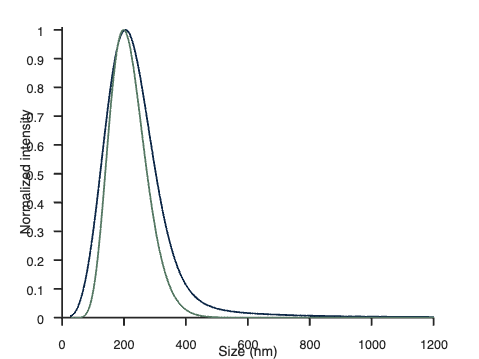

figure
hold on
plot(x_size(1:1349),PLGA_229_n(1:1349),'LineWidth',2,'color', '#0D2747'); % measured chrom
plot(x_size(1:1349),UV_PLGA_229(1:1349),'LineWidth',2,'color', '#567964'); % corrected chrom after UV cor
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
ax = gca;
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([0 1200]);
ylim([0 1.01]);
hold off
%legend('Measured','Corrected','UV corrected');
%legend('boxoff')
%legend('location','northeast')


% Calculate size peak parameters
for i = 1:length(idx_unique)
    for j = idx_unique(i)
        p1_229_UV(i) = UV_PLGA_229(j,:);      % population 1
    end
end

[hgts_UV, locs_UV, wds_UV] = findpeaks(p1_229_UV, x_unique(:,1), 'MinPeakHeight',0.9);
sigma_UV = [wds_UV/2.35];
var_UV = sigma_UV.^2;
p_229_UV = [locs_UV; sigma_UV; var_UV]';